PROJETO - 1ºPARTE

No ponto 1 recorremos a uma tabela para a estrutura de dados. Esta tabela contém colunas com as informações específicas dos ficheiros de áudio. O código percorre os ficheiros através de um ciclo for, extrai-mos o nome do ficheiro em partes de forma a obter o dígito e o número da repetição. Recorremos ao audioread de forma a carregar os áudio num array de valores. Os dados são inseridos na tabela T linha a linha e de seguida todos os dados são ordenados pela coluna "Repetição" para facilitar a organização. Decidimos colocar o numero de paciente fora do ciclo for, de forma a melhorar a eficiencia do codigo, pois este é o mesmo para todos os files audio.

folderPath = 'C:\Users\João Francisco\Documents\2ºAno\2Semestre\ATD\Projeto1\data\06';
files = dir(fullfile(folderPath, '*'));

filename = files(3).name;
participante = str2double(extractBetween(filename, '_', '_'));

T = table('Size', [0, 7], 'VariableTypes', {'string', 'string', 'double', 'double', 'double','cell','double'}, ...
          'VariableNames', {'Diretório', 'Nome_Ficheiro', 'Participante', 'Dígito', 'Repetição','Sinal','Taxa Amostragem'});

for i = 3:length(files)
    nome_ficheiro = files(i).name;
    diretorio = fullfile(folderPath, nome_ficheiro);
    parts = split(nome_ficheiro, '_');
    digito = str2double(parts{1});
    repeticao = str2double(extractBefore(parts{end}, '.'));
    [sinal, taxa] = audioread(diretorio);

    newRow = {diretorio, nome_ficheiro, participante, digito, repeticao,sinal,taxa};
    T = [T; newRow];
end
T = sortrows(T,"Repetição");
disp(T);

                                         Diretório                                          Nome_Ficheiro    Participante    Dígito    Repetição         Sinal          Taxa Amostragem
    ____________________________________________________________________________________    _____________    ____________    ______    _________    ________________    _______________

    "C:\Users\João Francisco\Documents\2ºAno\2Semestre\ATD\Projeto1\data\06\0_06_0.wav"     "0_06_0.wav"          6            0           0        {31228×1 double}         48000     
    "C:\Users\João Francisco\Documents\2ºAno\2Semestre\ATD\Projeto1\data\06\1_06_0.wav"     "1_06_0.wav"          6            1           0        {26423×1 double}         48000     
    "C:\Users\João Franci

No ponto 3 percorremos a tabela de forma a obter o sinal e os seus dados tal como a taxa, a amplitude e o tempo. E de seguida chama-mos uma função que nos permitirá visualizar as ondas de amplitude de cada áudio em função do tempo. Utilizamos uma programação dinâmica ao criar a lista digitos_plotados_original pois assim o codigo if não correrá deforma a melhorar a performance do código, caso esse dígito já tenha sido plotado.

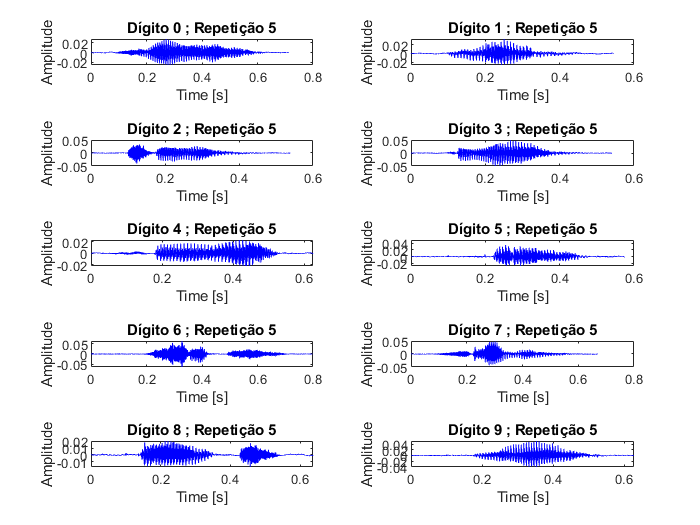

figure;
tiledlayout(5,2);
digitos_plotados_original = [];

for i = 1:height(T)
    digito = T.("Dígito")(i);
    sinal = (T.("Sinal"){i});
    taxa = T.("Taxa Amostragem")(i);
    t = (0:length(sinal)-1) / taxa;
    
    visualizar_digito(t,sinal,digito,digitos_plotados_original,T.("Repetição")(i))
end

Para melhorar a diferenciação entre dígitos, começamos pela normalização do áudio, descobrindo o máximo valor da amplitude e dividindo todos os valores de audio pelo mesmo. Após isto, optamos na utilização da função de energia para encontrar os indices finais e iniciais de som para cortar partes desnecessárias do audio isolando apenas na pronunciação do digíto. de seguida de forma a colocar-mos todos com o mesmo intrevalo de tempo, percorremos a tabela de sinal obtivemos o maior indice. Por fim como pedido no ponto 5 visualizamos os digitos utilizando a mesma função do ponto 3.

Como pedido no ponto 6 foi possível observar uma diferença na amplitude devido à normalização, neste no gráfico no exercício 5 apresenta uma amplitude mais nivelada. O silêncio inicial e final inicializou a pronúncia do dígito mais cedo, porém poderá haver um mínimo corte no áudio devido ao cálculo dos intervalos para o ajuste.  A visualização dos gráficos tornou-se mais simples devido ao acrescento de silêncio no final dos áudios de forma a tornar o tempo dos mesmos iguais.

No ponto 7, dentro do ciclo que percorre a tabela, para cada sinal de áudio, fomos calcular a amplitude mínima e máxima. A energia total, através da soma dos quadrados das amplitudes do sinal. A média de amplitude, a partir da média dos valores absolutos do sinal e por fim a variância da amplitude, que mede a dispersão dos valores da amplitude em torno da média. De seguida cada valor calculado é armazenado numa lista própria na posição correspondente ao dígito. Para o ponto 8, recorremos à função graficos(lista,label) damos plot nos gráficos, cada ponto no gráfico corresponde a um valor extraido de um áudio específico.

  
figure;
tiledlayout(5,2);

digitos_plotados = [];

lista_maximo = cell(1, 10);
lista_variancia = cell(1, 10);
lista_zcr = cell(1, 10);
lista_tempo_pico = cell(1, 10); 
lista_frequencia_dominante = cell(1, 10);
lista_skewness = cell(1, 10);

max_indice_fim = encontrar_maior_indice_fim(T);

zona do sinal processado


for i = 1:height(T)
    digito = T.("Dígito")(i);
        
    sinal = (T.("Sinal"){i});
    maxsinal = max(abs(sinal));
    sinal = sinal/maxsinal;
    taxa = T.("Taxa Amostragem")(i);         
    
    indice_inicio = encontrar_inicio_sinal(sinal);
    indice_fim = length(sinal) - encontrar_inicio_sinal(flip(sinal)) + 1;
    
    sinal = sinal(indice_inicio:indice_fim); % Mantém apenas a parte útil do áudio
    sinal(end+1:max_indice_fim) = 0;
    t = (0:length(sinal)-1) / taxa;
    
    visualizar_digito(t,sinal,digito,digitos_plotados,T.("Repetição")(i))
    
    T.Sinal{i} = sinal;

Zona das Caracteristicas    

    %Variância do sinal
    var = 0;
    %media_amplitude = mean(abs(sinal));
    for j = 1:length(sinal)
        var = var + (abs(sinal(j)) - media_amplitude)^2;
    end
    var = sqrt(var/(length(sinal)-1));
    
    %Vezes que o sinal passa no zero
    zero_crossings = sum(abs(diff(sign(sinal)))) / 2;
    
    %Tempo até pico maximo
    [~, indice_pico] = max(abs(sinal));
    tempo_pico = indice_pico / taxa; 
    
    % Aplicar FFT para obter a frequência dominante
    N = length(sinal);
    Y = fft(sinal);
    f = (0:N-1) * (taxa / N); 
    Y_magnitude = abs(Y(1:floor(N/2))); 
    f_positive = f(1:floor(N/2));

    [~, idx] = max(Y_magnitude);
    freq_dominante = f_positive(idx); 
    
    % Assemtria do digito
    skewness_val = skewness(sinal);

    % Armazenar na lista
    lista_skewness{digito + 1} = [lista_skewness{digito + 1}, skewness_val];
    lista_frequencia_dominante{digito + 1} = [lista_frequencia_dominante{digito + 1}, freq_dominante];
    lista_tempo_pico{digito + 1} = [lista_tempo_pico{digito + 1}, tempo_pico];
    lista_zcr{digito + 1} = [lista_zcr{digito + 1}, zero_crossings];
    lista_maximo{digito + 1} = [lista_maximo{digito + 1}, maxsinal]; 
    lista_variancia{digito + 1} = [lista_variancia{digito + 1}, var];
end

Unrecognized function or variable 'media_amplitude'.


sgtitle('Gráficos dos Áudios Originais');

Plot Dos Gráficos


graficos(lista_maximo,'Máximo Amplitude')
graficos(lista_variancia,'Variância')
graficos(lista_zcr, 'Zero-Crossing Rate');
graficos(lista_tempo_pico, 'Tempo até o Pico Máximo (s)');
graficos(lista_frequencia_dominante, 'Frequência Dominante (Hz)');
graficos(lista_skewness, 'Assimetria (Skewness)');
graficos3D(lista_maximo,lista_variancia,lista_zcr,'Máximo Amplitude','Variância','Zero-Crossing Rate');
graficos3D(lista_maximo,lista_tempo_pico,lista_frequencia_dominante,'Máximo Amplitude','Tempo até o Pico Máximo (s)','Frequência Dominante (Hz)');
graficos3D(lista_maximo,lista_skewness,lista_variancia,'Máximo Amplitude','Assimetria (Skewness)','Variância');
graficos3D(lista_zcr,lista_tempo_pico,lista_skewness,'Zero-Crossing Rate','Tempo até o Pico Máximo (s)','Assimetria (Skewness)');

T_final = removevars(T,("Sinal"));
save('projeto.mat', 'T_final');
save('table.mat','T');


No ponto 9, removemos da tabela os dados "Sinal", e guardamos num ficheiro .mat.


function index = encontrar_inicio_sinal(sinal)
    limiar = 0.5;
     
    janela = 10; % Tamanho da janela deslizante
    energia_local = movsum(sinal.^2, janela); % Energia acumulada em uma janela deslizante

    % Encontra o primeiro índice onde a energia é maior que o limiar
    index = find(energia_local > limiar, 1, 'first');

    % Caso não encontre (exemplo: sinal muito baixo), retorna 1
    if isempty(index)
        index = 1;
    end
end

function max_indice_fim = encontrar_maior_indice_fim(T)
    max_indice_fim = 0; % Inicializa o maior índice encontrado

    for i = 1:height(T)
        if T.("Repetição")(i) == 5
            sinal = T.("Sinal"){i}; % Obtém o sinal
            maxsinal = max(abs(sinal));
            sinal = sinal / maxsinal;
           
            indice_fim = encontrar_inicio_sinal(flip(sinal));
            indice_fim = length(sinal) - indice_fim + 1;
    
            if indice_fim > max_indice_fim
                max_indice_fim = indice_fim;
            end
        end
    end
end


function graficos(lista,label)

    figure;
    hold on;
    for d = 1:10
        if ~isempty(lista{d})
            
            plot(repmat(d-1, 1, length(lista{d})), lista{d}, 'o');
        end
    end
    xlabel('Dígitos');
    ylabel(label);
    title('CARACTERISTICAS DE IDENTIFICAÇÃO DE DIGITOS');
    grid on;
    hold off;
end


function visualizar_digito(t,sinal,digito,digitos_plotados,repeticao)

    if ~ismember(digito, digitos_plotados) && repeticao == 5
        nexttile;
        plot(t, sinal, 'b');  
        xlabel('Time [s]'); ylabel('Amplitude');
        
        title(sprintf('Dígito %d ; Repetição %d', digito, repeticao)); 
        
        digitos_plotados = [digitos_plotados, digito];
    end
end

function graficos3D(lista_x, lista_y, lista_z, label_x, label_y, label_z)
    figure;
    hold on;
    
    for d = 1:10
        if ~isempty(lista_x{d}) && ~isempty(lista_y{d}) && ~isempty(lista_z{d})
            % Converte as listas para vetores para garantir que scatter3 funcione corretamente
            x = lista_x{d}(:);
            y = lista_y{d}(:);
            z = lista_z{d}(:);
            
            scatter3(x, y, z, 50, 'o'); % Usa cores automáticas e garante 3D
        end
    end

    xlabel(label_x);
    ylabel(label_y);
    zlabel(label_z);
    title('Distribuição das Características do Áudio');

    % Criar legenda correspondente aos dígitos
    legendStrings = arrayfun(@num2str, 0:9, 'UniformOutput', false);
    legend(legendStrings, 'Location', 'eastoutside');

    grid on;
    view(3); % Garante que a visualização esteja em 3D
    hold off;
end

